clc;
clear;
close all;
x1=[1 2 3 5 6 4];
disp(x1);

     1     2     3     5     6     4



x2=[1 5 3 4 8];
disp(x2);

     1     5     3     4     8



l=max(length(x2),length(x1));

xp1=[x1,zeros(1,l-length(x1))]

xp1 =      1     2     3     5     6     4


xp2=[x2,zeros(1,l-length(x2))]

xp2 =      1     5     3     4     8     0


xp3=zeros(l,l)

xp3 =      0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0



for i=1:l
    for j=1:l
        k=rem((i+l-j),l)+1;
        xp3(i,j)=xp2(k);
    end
end

xp3

xp3 =      1     0     8     4     3     5
     5     1     0     8     4     3
     3     5     1     0     8     4
     4     3     5     1     0     8
     8     4     3     5     1     0
     0     8     4     3     5     1


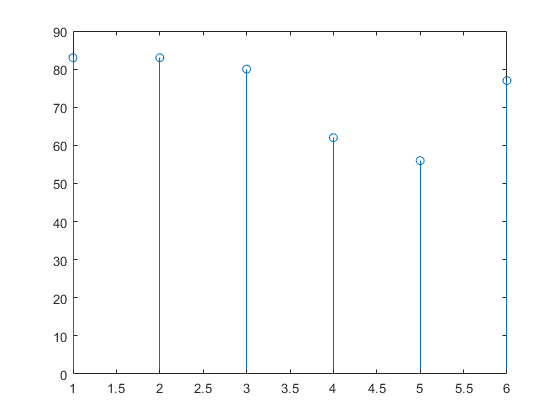

y=xp3*transpose(xp1);
stem(y);


% ccirc = ifft(fft(xp1).*fft(xp2));
% disp(ccirc);
disp(cconv(xp1,xp2,6))

    83    83    80    62    56    77

